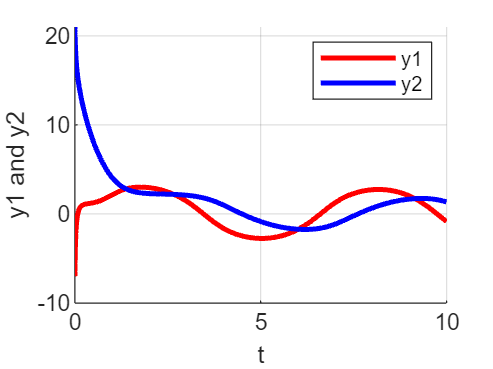

clc;clear;
tspan = [0,10];
x0 = [5;-6];
%%仿真
[t,x] = ode45(@odefun,tspan,x0);
y(:,1) =x(:,1) + 2*x(:,2);
y(:,2) =3*x(:,1) - x(:,2);

figure(1);
hold on;
grid on;
plot(t,y(:,1),"r","LineWidth",2);
plot(t,y(:,2),"b","LineWidth",2);
legend("y1","y2");
xlabel("t");ylabel("y1 and y2");

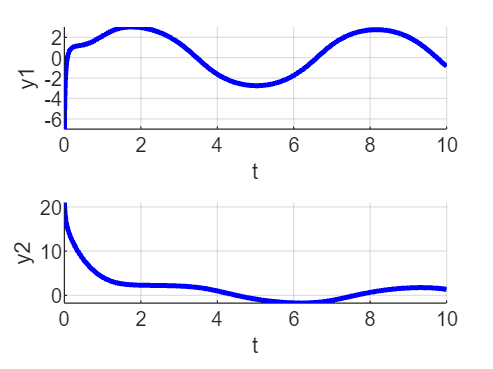


figure(2);
subplot(2,1,1);
hold on;
grid on;
plot(t,y(:,1),"b","LineWidth",2);
xlabel("t");ylabel("y1");
subplot(2,1,2);
hold on;
grid on;
plot(t,y(:,2),"b","LineWidth",2);
xlabel("t");ylabel("y2");



%%函数

function dx = odefun(t,x)
    x1=x(1);
    x2=x(2);
    dx1 = -x1 + x2;
    dx2 = -x1 - 3*x2 - x2^3 +5*sin(t);
    dx = [dx1;dx2];
end